%% Parameters
ref_location = [40.437675, -86.943750, 680]; % LLA initial position
ref_mag_field = [19.78899, -1.607, 48.9449]; % NED magnetic field

% initial state of the filter
initstate = zeros(28,1);
%orientation
initstate(1:4) = [1 0 0 0]; 
% magnetic field
initstate(23:25) = ref_mag_field;
 
%% Extract Raw Data
Digital_Signals = out.Digital_Signals;
Vehicle_Signals = out.Vehicle_Signals;
Orientation_all = out.Chassis_Orientation;
IMU_Signals = out.IMU_Measurements;
Reference_Signals = out.Navigation_Reference;
Fused_Signals = out.Sensor_Fused;

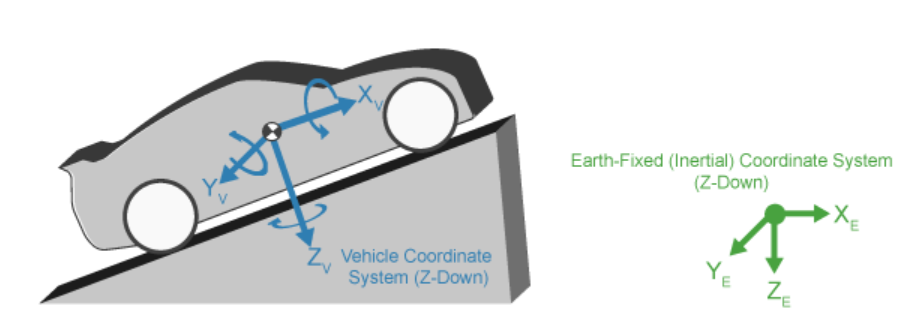

%% Before Sensor Signals
% Orientation before IMU using NED (Earth-Fixed Coordinate System)
% Orientation = quaternion(squeeze(Orientation_all.ang_NED.data)');
% Orientation_REF = euler(Orientation, 'XYZ', 'frame');
% Orientation_FUS = squeeze(Fused_Signals.ang_euler_NED.Data)';

Orientation = squeeze(Reference_Signals.Chassis_Orientation.Data);
Orientation_FUS = quaternion(squeeze(Fused_Signals.ang_NED.data)');
Orientation_FUS = euler(Orientation_FUS, 'XYZ', 'frame');

ang_error = rad2deg(Orientation_REF - Orientation_FUS);
ang_error = ang_error + ((ang_error > 350).*-360) + ((ang_error < -350).*360);
ang_norm_error = vecnorm(ang_error');

Orientation = quaternion(Orientation, 'euler', 'XYZ', 'frame');

% Geomagnetic Field Vector before IMU using VNED
% GeomagneticFieldVector = Orientation_all.rotm*ref_mag_field;

% Position before GPS using NED (Earth-Fixed Coordinate System)
PositionX_REF = Reference_Signals.Chassis_Position.X.data(:);
PositionY_REF = Reference_Signals.Chassis_Position.Y.data(:);
PositionZ_REF = Reference_Signals.Chassis_Position.Z.data(:);

Position = [PositionX_REF PositionY_REF PositionZ_REF];

% Angular Velocity before IMU using VNED (Vehicle-Fixed Coordinate System)
AngularVelocity_p_REF = Reference_Signals.Chassis_AngularVelocity.Data(:,1);
AngularVelocity_q_REF = Reference_Signals.Chassis_AngularVelocity.data(:,2);
AngularVelocity_r_REF = Reference_Signals.Chassis_AngularVelocity.data(:,3);

AngularVelocity_REF = [AngularVelocity_p_REF AngularVelocity_q_REF AngularVelocity_r_REF];

% Velocity before GPS using NED (Earth-Fixed Coordinate System)
VelocityX_REF = Reference_Signals.Chassis_Velocity_NED.Xdot.Data(:);
VelocityY_REF = Reference_Signals.Chassis_Velocity_NED.Ydot.Data(:);
VelocityZ_REF = Reference_Signals.Chassis_Velocity_NED.Zdot.Data(:);

Velocity_REF = [VelocityX_REF VelocityY_REF VelocityZ_REF];

% Acceleration before IMU using NED (Earth-Fixed Coordinate System)
AccelerationX_REF = Reference_Signals.Chassis_Acceleration.Data(:,1);
AccelerationY_REF = Reference_Signals.Chassis_Acceleration.Data(:,2);
AccelerationZ_REF = Reference_Signals.Chassis_Acceleration.Data(:,3);

Acceleration_REF = [AccelerationX_REF AccelerationY_REF AccelerationZ_REF];

%% After Sensor Signals
% Magnetometer readings after IMU using VNED (Vehicle Coordinate System)
Magnetometer = squeeze(IMU_Signals.IMU_mag.data)';

% Position readings after IMU using NED (Earth-Fixed Coordinate System)
GPSPosition = Digital_Signals.Navigation_Sensors.pos.Data(:,:);

GPSPosition = lla2ned(GPSPosition,ref_location,'flat');

% Angular Velocity readings after IMU using VNED (Vehicle Coordinate System)
Gyroscope = squeeze(IMU_Signals.IMU_gyro.Data)';

% Velocity readings after IMU using NED (Earth-Fixed Coordinate System)
GPSVelocity = Digital_Signals.Navigation_Sensors.vel.Data(:,:);

% Acceleration readings after IMU using VNED (Vehicle Coordinate System)
Accelerometer = IMU_Signals.IMU_accel.Data(:,:)';

%% Create Datasets
groundTruth = timetable(Orientation, Position, 'SampleRate', 1/fusion_t);
sensorData = timetable(Accelerometer, Gyroscope, Magnetometer, GPSPosition, GPSVelocity, 'SampleRate', 1/fusion_t);

%% Fusion Optimization
filter = insfilterAsync('State', initstate, 'StateCovariance', eye(28)./1000, ...
    'AccelerometerBiasNoise', 1e-7, ...
    'GyroscopeBiasNoise', 1e-7, ...
    'MagnetometerBiasNoise', 1e-7, ...
    'GeomagneticVectorNoise', 1e-7);

filter.ReferenceLocation = ref_location;

config = tunerconfig('insfilterAsync','MaxIterations',16);

config.TunableParameters = setdiff(config.TunableParameters, ...
    {'GeomagneticVectorNoise', 'AccelerometerBiasNoise', ...
    'GyroscopeBiasNoise', 'MagnetometerBiasNoise'});

measNoise = tunernoise('insfilterAsync');

tunedParams = tune(filter,measNoise,sensorData,groundTruth,config);

[Degree to Decimal LLA Calculator](https://www.meridianoutpost.com/resources/etools/calculators/calculator-latlong-dms-to-decimal.php/?)

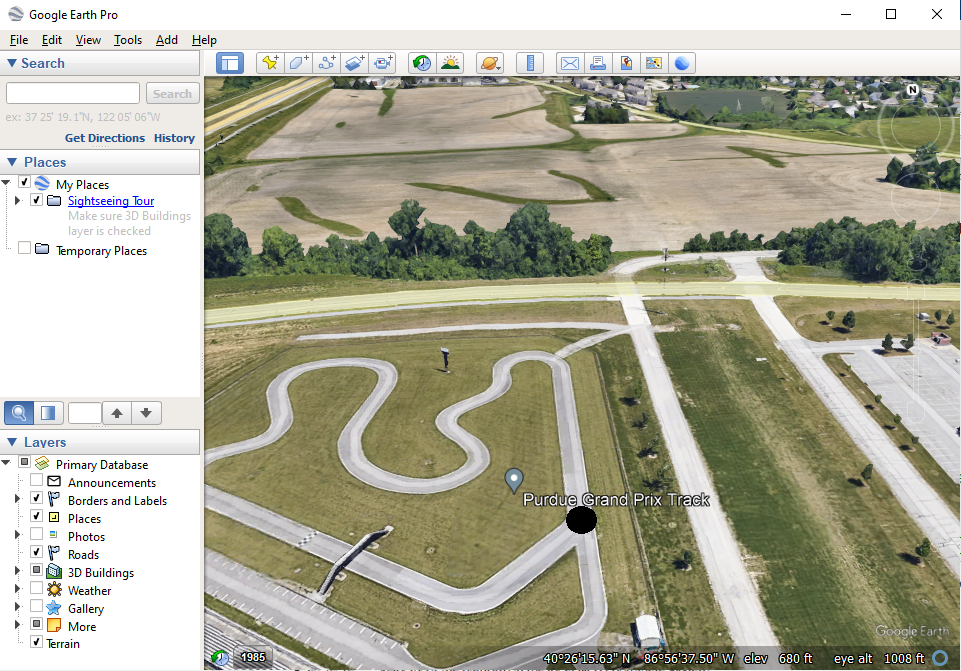

% LLA of grand prix track
PER22_Ground_Truth.refloc = [40.437675, -86.943750, 680]; % [deg deg m]

[Magnetic Field Calculator](https://www.ngdc.noaa.gov/geomag/calculators/magcalc.shtml#igrfwmm)

[More Information About Geomagnetic Fields | NCEI (noaa.gov)](https://www.ngdc.noaa.gov/geomag/geomaginfo.shtml)

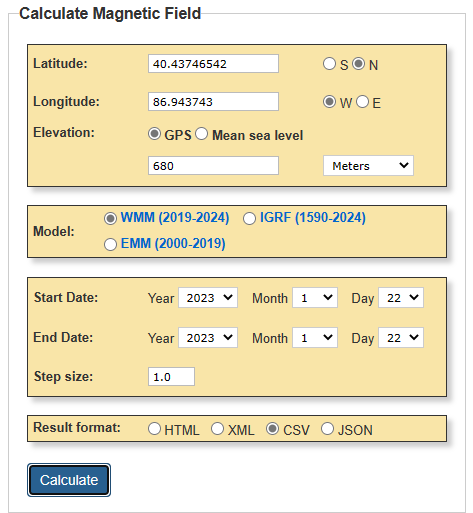

% XYZ magnetic field components at grand prix track
% note that magnetic north and true north are not equal
PER22_Ground_Truth.magField = [19.9577 -1.5449 48.4109]; % [uT uT uT]

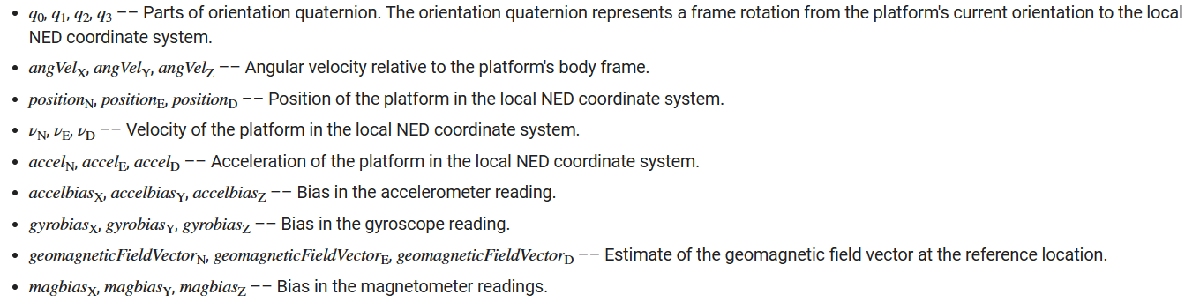

%% Process Data
num_samples = 1001;
count = 1;
orient = zeros(num_samples,1,'quaternion');
vel = zeros(num_samples,3);
acc = vel;
angVel = vel;
pos = vel;

trajectory = waypointTrajectory(Position, 'TimeOfArrival',(0:t:15), 'Orientation',Orientation, 'SampleRate', 1/t);
tInfo = waypointInfo(trajectory);

while count < num_samples+1
   [pos(count,:),orient(count),vel(count,:),acc(count,:),angVel(count,:)] = trajectory();

   count = count + 1;
end

%% Create Trajectory Struct (Sample rate of Simulation)
PER22_Ground_Truth.Fs = 1/t;
PER22_Ground_Truth.gpsFs = 1/t;

% Orientation using NED (Earth-Fixed Coordinate System)
PER22_Ground_Truth.trajData.Orientation = Orientation;

% Position using NED (Earth-Fixed Coordinate System)
PER22_Ground_Truth.trajData.Position = Position;

% Velocity using NED (Earth-Fixed Coordinate System)
PER22_Ground_Truth.trajData.Velocity = vel;

% Angular Velocity using VNED (Vehicle Coordinate System)
PER22_Ground_Truth.trajData.AngularVelocity = AngularVelocity_REF;

% Acceleration using NED (Earth-Fixed Coordinate System)
PER22_Ground_Truth.trajData.Acceleration = acc;

% plot((0:t:15), acc(:,2))
% plot((0:t:15), angVel(:,3))
% hold on
% plot(out.yaw_error.Time, PER22_Ground_Truth.trajData.AngularVelocity(:,3))

clearvars -except PER22_Ground_Truth
save("ground_truth_data.mat");